## **Waterfilling**

%create a string

SNR = -15:1:15;
length_of_vetor = 1e6;
nc = 1e4;
x = randi([1,2],1,length_of_vetor);
x(x==2) = -1;

number_of_vectors = size(SNR,2);
L = 200;
CP = L - 1;
h = complex_normal(1,1,L);
H = fft(h,nc);
P_max = 1;

### P_i Algorithm

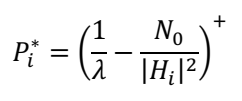

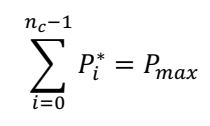

% It will cost a lot of time
lambda = 0.2;
iter = 10000; % higher better
Pi_start = rand(1,nc); 
epsilon = 0.1; %for better result this should be smaller
for j=1:size(SNR,2)
  Pi = Pi_start;  
 while(iter)
     if(abs((P_max-sum(Pi))) < epsilon)
         p_opt(j) = Pi;
         break
     else
         for i=1:nc        
             Pi(i) = max((1/lambda)-(P_max./(10.^(SNR(j)/10))/nc/abs(H(i)).^2),0);
         end   
     end
     lambda = lambda+0.01;
     iter = iter -1;
 end
end
%if it doesnt found the p_opt, just higher the iter parameter or assign
%p_opt = pi after a lot of iters.

for j=1:number_of_vectors
for i=1:(length_of_vetor/nc)

    %Water Filling if it is needed.
    x_waterfiling = (x((i-1)*(nc)+1:i*(nc))).*P_opt;
    
    %IFFT from the string nc points --> Xk
    Xk = ifft(x_waterfiling,nc);
    
    %adding CP to Xk (199 from end will be added to the first of string)
    Xk_cp = [Xk(end-(CP-1):end),Xk];
    
    % nc + CP + L - 1 = nc + 2CP = M
    M = nc + 2*CP;
    
    %Now we should go through channel --> Convolve with h (random Generated)
    y = conv(Xk_cp,h);
    
    %noise generating
    w(j,(i-1)*(M)+1:i*(M)) = sqrt(P_max./(10.^(SNR(j)/10))/nc/2).*randn(1,M)+1i.*sqrt(P_max./(10.^(SNR(j)/10))/nc/2).*randn(1,M);
    
    Y_w = w(j,(i-1)*(M)+1:i*(M)) + y;
    
    % 199 from first and end should be omitted.
    Yk_w_no_cp = Y_w(200:end-199);
    
    %Now We should FFT from it
    bb = fft(Yk_w_no_cp,nc);
    yk(j,(i-1)*nc+1:i*nc) = fft(Yk_w_no_cp,nc);
end

end

Equalized_y = yk;
Equalized_y(real(Equalized_y)>0) = 1;
Equalized_y(real(Equalized_y)<0) = -1;

x = repmat(x,number_of_vectors,1);
temp = x-Equalized_y;

err_prob = error_probability(temp);

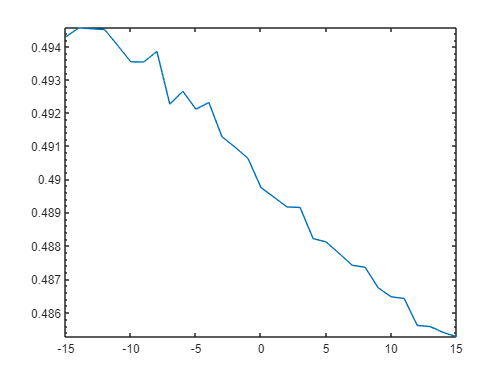

semilogy(SNR,err_prob);

### Capacitance

V = (P_opt.*(abs(H).^2))

V =    28.6117    7.8518    5.3645   10.8154   11.0662    0.6269    0.5326    4.1793    2.3746    1.4688    2.0484    2.5586    3.8902    6.9113    9.6092    1.3355   11.2497   24.8423    7.4305   22.7329   41.1011   20.3463   13.9719    4.8755   68.4460   49.8088   92.7509   83.7960   87.9017   58.5576   62.8014  135.0148   59.9128   97.7704   79.9890   69.2118  180.7727  106.5278  132.4389  101.5924  172.4899   57.6734   79.2149  111.3979   21.2845   30.4352   18.4979  204.9511  168.8878  213.5426


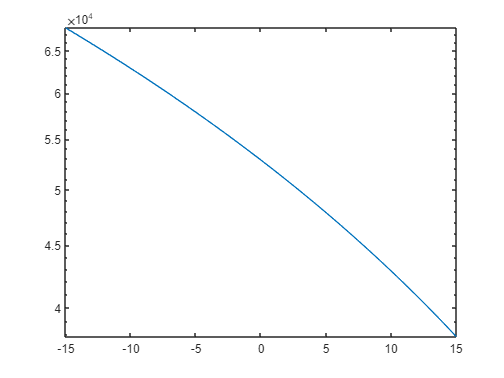

N0 = (10.^(SNR./10))/nc;
for i=1:length(N0)
C(i) = sum(log10(1+V/N0(i)));
end

semilogy(SNR,C);

## ZF

%create a string

SNR = -15:1:15;
length_of_vetor = 1e6;
nc = 1e4;
x = randi([1,2],1,length_of_vetor);
x(x==2) = -1;

number_of_vectors = size(SNR,2);


L = 200;
CP = L - 1;
h = complex_normal(1,1,L);
H = fft(h,nc);
P_max = 1;

for j=1:number_of_vectors
for i=1:(length_of_vetor/nc)

    %Water Filling if it is needed.
    x_waterfiling = (x((i-1)*(nc)+1:i*(nc)));
    
    %IFFT from the string nc points --> Xk
    Xk = ifft(x_waterfiling,nc);
    
    %adding CP to Xk (199 from end will be added to the first of string)
    Xk_cp = [Xk(end-(CP-1):end),Xk];
    
    % nc + CP + L - 1 = nc + 2CP = M
    M = nc + 2*CP;
    
    %Now we should go through channel --> Convolve with h (random Generated)
    y = conv(Xk_cp,h);
    
    %noise generating
    w(j,(i-1)*(M)+1:i*(M)) = sqrt(P_max./(10.^(SNR(j)/10))/nc/2).*randn(1,M)+1i.*sqrt(P_max./(10.^(SNR(j)/10))/nc/2).*randn(1,M);
    
    Y_w = w(j,(i-1)*(M)+1:i*(M)) + y;
    
    % 199 from first and end should be omitted.
    Yk_w_no_cp = Y_w(200:end-199);
    
    %Now We should FFT from it
    bb = fft(Yk_w_no_cp,nc);
    yk(j,(i-1)*nc+1:i*nc) = fft(Yk_w_no_cp,nc);

    %ZF = 1/Hk 
    yk(j,(i-1)*nc+1:i*nc) = yk(j,(i-1)*nc+1:i*nc)./H;

end

end

Equalized_y = yk;
Equalized_y(real(Equalized_y)>0) = 1;
Equalized_y(real(Equalized_y)<0) = -1;

x = repmat(x,number_of_vectors,1);
temp = x-Equalized_y;

err_prob = error_probability(temp);

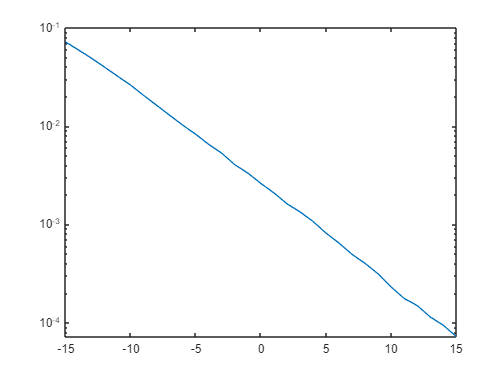

semilogy(SNR,err_prob);

## MMSE

%create a string

SNR = -15:1:15;
length_of_vetor = 1e6;
nc = 1e4;
x = randi([1,2],1,length_of_vetor);
x(x==2) = -1;

number_of_vectors = size(SNR,2);


L = 200;
CP = L - 1;
h = complex_normal(1,1,L);
H = fft(h,nc);
P_max = 1;

for j=1:number_of_vectors
for i=1:(length_of_vetor/nc)

    %Water Filling if it is needed.
    x_waterfiling = (x((i-1)*(nc)+1:i*(nc)));
    
    %IFFT from the string nc points --> Xk
    Xk = ifft(x_waterfiling,nc);
   

    %adding CP to Xk (199 from end will be added to the first of string)
    Xk_cp = [Xk(end-(CP-1):end),Xk];
    
    % nc + CP + L - 1 = nc + 2CP = M
    M = nc + 2*CP;
    
    %Now we should go through channel --> Convolve with h (random Generated)
    y = conv(Xk_cp,h);
    
    %noise generating
    w(j,(i-1)*(M)+1:i*(M)) = sqrt(P_max./(10.^(SNR(j)/10))/nc/2).*randn(1,M)+1i.*sqrt(P_max./(10.^(SNR(j)/10))/nc/2).*randn(1,M);
    
    Y_w = w(j,(i-1)*(M)+1:i*(M)) + y;
    
    % 199 from first and end should be omitted.
    Yk_w_no_cp = Y_w(200:end-199);
    
    %Now We should FFT from it
    
    yk(j,(i-1)*nc+1:i*nc) = fft(Yk_w_no_cp,nc);

    % or MMSE in the notes
    N0 = P_max./(nc*(10.^(SNR(j)/10)));
    wk = conj(H)./(abs(H).^2 + N0);

    yk(j,(i-1)*nc+1:i*nc) = yk(j,(i-1)*nc+1:i*nc).*wk;

end

end

Equalized_y = yk;
Equalized_y(real(Equalized_y)>0) = 1;
Equalized_y(real(Equalized_y)<0) = -1;

x = repmat(x,number_of_vectors,1);
temp = x-Equalized_y;

err_prob = error_probability(temp);

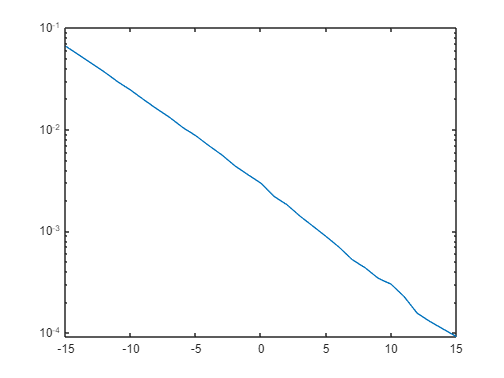

semilogy(SNR,err_prob);

## **Diversity**

%create a string

SNR = -15:1:15;
length_of_vetor = 1e6;
nc = 1e4;
x = randi([1,2],1,length_of_vetor);
x(x==2) = -1;

number_of_vectors = size(SNR,2);


L = 200;
CP = L - 1;
h = complex_normal(1,1,L);
H = fft(h,nc);
P_max = 1;

for j=1:number_of_vectors
for i=1:(length_of_vetor/nc)

    %Water Filling if it is needed.
    x_waterfiling = (x((i-1)*(nc)+1:i*(nc)));
    
    %IFFT from the string nc points --> Xk
    Xk = ifft(x_waterfiling,nc);
    
    %adding CP to Xk (199 from end will be added to the first of string)
    Xk_cp = [Xk(end-(CP-1):end),Xk];
    
    % nc + CP + L - 1 = nc + 2CP = M
    M = nc + 2*CP;
    
    %Now we should go through channel --> Convolve with h (random Generated)
    y = conv(Xk_cp,h);
    angle_h = angle(h);

    yk(j,(i-1)*nc+1:i*nc) = 0;
    %noise generating
    for k=1:10
        w(k,(i-1)*(M)+1:i*(M)) = sqrt(P_max./(10.^(SNR(j)/10))/nc/2).*randn(1,M)+1i.*sqrt(P_max./(10.^(SNR(j)/10))/nc/2).*randn(1,M);
        Y_w = w(k,(i-1)*(M)+1:i*(M)) + y;
        % 199 from first and end should be omitted.
        Yk_w_no_cp = Y_w(200:end-199);
        %Now We should FFT from it
        bb = fft(Yk_w_no_cp,nc);
        %cophasing
        bb = bb.*(conj(H)/sum(abs(H)));
        yk(j,(i-1)*nc+1:i*nc) = yk(j,(i-1)*nc+1:i*nc) + bb;
    end
       
end

end
w = 0;
Y_w = 0;

Equalized_y = yk;
Equalized_y(real(Equalized_y)>0) = 1;
Equalized_y(real(Equalized_y)<0) = -1;

x = repmat(x,number_of_vectors,1);
temp = x-Equalized_y;

err_prob = error_probability(temp);

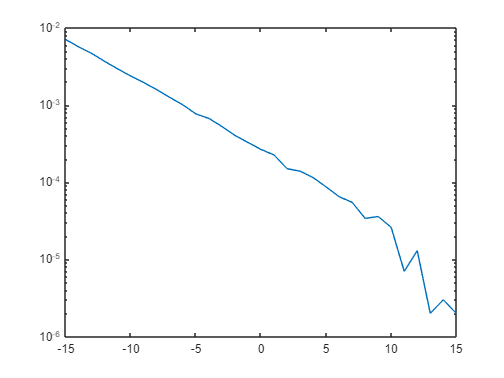

semilogy(SNR,err_prob); 

## Question 8.

%create a string

SNR = -15:1:15;
length_of_vetor = 1e6;
nc = 1e4;
x = randi([1,2],1,length_of_vetor);
x(x==2) = -1;

number_of_vectors = size(SNR,2);


L = 200;
CP = L - 1;
h = complex_normal(1,1,L);
H = fft(h,nc);
P_max = 1;

for j=1:number_of_vectors
for i=1:(length_of_vetor/nc)

    %Water Filling if it is needed.
    x_waterfiling = (x((i-1)*(nc)+1:i*(nc)));
    
    %IFFT from the string nc points --> Xk
    Xk = ifft(x_waterfiling,nc);
    
    %Clipping
    Xk(Xk>0.8*max(abs(Xk))) = 0.8*max(abs(Xk));

    %adding CP to Xk (199 from end will be added to the first of string)
    Xk_cp = [Xk(end-(CP-1):end),Xk];
    
    % nc + CP + L - 1 = nc + 2CP = M
    M = nc + 2*CP;
    
    %Now we should go through channel --> Convolve with h (random Generated)
    y = conv(Xk_cp,h);
    
    %noise generating
    w(j,(i-1)*(M)+1:i*(M)) = sqrt(P_max./(10.^(SNR(j)/10))/nc/2).*randn(1,M)+1i.*sqrt(P_max./(10.^(SNR(j)/10))/nc/2).*randn(1,M);
    
    Y_w = w(j,(i-1)*(M)+1:i*(M)) + y;
    
    % 199 from first and end should be omitted.
    Yk_w_no_cp = Y_w(200:end-199);
    
    %Now We should FFT from it
    
    yk(j,(i-1)*nc+1:i*nc) = fft(Yk_w_no_cp,nc);

    % or MMSE in the notes
    N0 = P_max./(nc*(10.^(SNR(j)/10)));
    wk = conj(H)./(abs(H).^2 + N0);

    yk(j,(i-1)*nc+1:i*nc) = yk(j,(i-1)*nc+1:i*nc).*wk;

end

end

Equalized_y = yk;
Equalized_y(real(Equalized_y)>0) = 1;
Equalized_y(real(Equalized_y)<0) = -1;

x = repmat(x,number_of_vectors,1);
temp = x-Equalized_y;

err_prob = error_probability(temp);

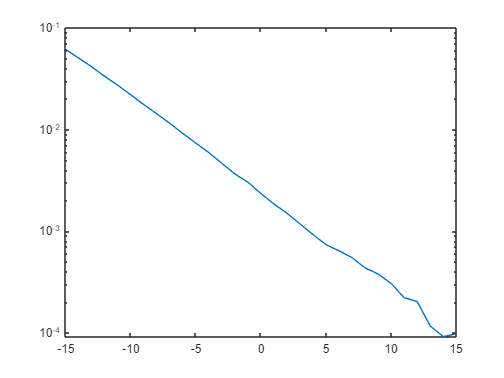

semilogy(SNR,err_prob);

Functions.

function Q = complex_normal(number_of_vectors,N0,length_of_vetor) 
Q = zeros(number_of_vectors,length_of_vetor);
for i=1:number_of_vectors
    Q_re = N0(i)/2*randn(1,length_of_vetor);
    Q_im = N0(i)/2*randn(1,length_of_vetor);
    Q(i,:) = Q_re + 1i*Q_im;
end
end
function err_prob = error_probability(temp)
s = size(temp);
err_prob = zeros(s(1,1),1);
for i=1:s(1,1)
    err_prob(i,1) = nnz(temp(i,:))/s(1,2);
end
end